# Atividade 2 - Análise de Sinais

## Item A - Calculo valor médio e RMS

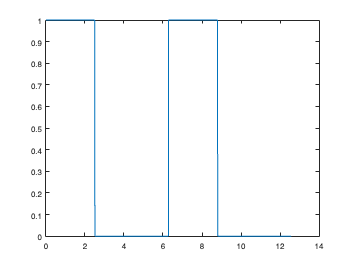

T = 2 * pi;
duty_cycle = 40;

x = 0:0.01:4*pi;
y = (square(x, duty_cycle) + 1) .* 0.5;

plot(x, y)

mean_value= mean(y)

mean_value = 0.4002

rms_value = rms(y)

rms_value = 0.6326

n = [1:100]';
t = x;
A = 1;
t_on = T .* duty_cycle ./ 100;
omega = (2 .* pi) ./ T;

A0 = A * (duty_cycle ./ 100);
An = (A ./ (n .* pi)) .* sin(n .* omega .* t_on);
Bn = (A ./ (n .* pi)) .* (1 - cos(n .* omega .* t_on)); % !!!!

partial = [An .* cos(n .* omega .* x) + Bn .* sin(n .* omega .* t)]'

partial =     0.1871   -0.1514    0.1009   -0.0468   -0.0000    0.0312   -0.0432    0.0378   -0.0208   -0.0000    0.0170   -0.0252    0.0233   -0.0134   -0.0000    0.0117   -0.0178    0.0168   -0.0098   -0.0000    0.0089   -0.0138    0.0132   -0.0078   -0.0000    0.0072   -0.0112    0.0108   -0.0065   -0.0000    0.0060   -0.0095    0.0092   -0.0055   -0.0000    0.0052   -0.0082    0.0080   -0.0048   -0.0000    0.0046   -0.0072    0.0070   -0.0043   -0.0000    0.0041   -0.0064    0.0063   -0.0038   -0.0000
    0.1928   -0.1491    0.1031   -0.0410   -0.0000    0.0369   -0.0409    0.0399   -0.0150   -0.0000    0.0227   -0.0229    0.0253   -0.0075   -0.0000    0.0173   -0.0154    0.0187   -0.0039   -0.0000    0.0144   -0.0112    0.0150   -0.0019   -0.0000    0.0126   -0.0086    0.0126   -0.0005   -0.0000    0.0114   -0.0068    0.0108    0.0005   -0.0000    0.0105   -0.0055    0.0095    0.0012   -0.0000    0.0098   -0.0044    0.0085    0.0017   -0.0000    0.0092   -0.0036    0.0077    0.002

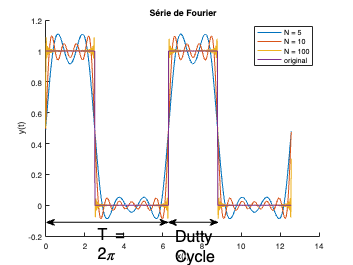

final   = sum(partial, 2);

clf; hold on;
plot(x, A0 + sum(partial(:,1:5),2));
plot(x, A0 + sum(partial(:,1:10),2));
plot(x, A0 + final);
plot(x, y);

legend('N = 5', 'N = 10', 'N = 100', 'original');
title('Série de Fourier');
xlabel('x(t)'), ylabel('y(t)');

figure = gcf;
annotation(figure,'doublearrow',[0.13203125 0.475315729047072],...
    [0.160935350756534 0.160935350756534]);

% Create doublearrow
annotation(figure,'doublearrow',[0.47734375 0.6171875],...
    [0.160935350756534 0.160935350756534]);

% Create textbox
annotation(figure,'textbox',...
    [0.261937500000001 0.0962861072902338 0.123218749999999 0.0591471801925723],...
    'String','T = 2\pi',...
    'FontSize',20,...
    'FitBoxToText','off',...
    'EdgeColor','none');

% Create textbox
annotation(figure,'textbox',...
    [0.48359375 0.10041265474553 0.154687500000001 0.0591471801925723],...
    'String','Dutty Cycle = 0.4',...
    'FontSize',20,...
    'FitBoxToText','off',...
    'EdgeColor','none');

hold off;

valor_medio_armonico_1 = mean(partial(:, 1) + A0)

valor_medio_armonico_1 = 0.4001

valor_rms_armonico_1 = rms(partial(:, 1) + A0)

valor_rms_armonico_1 = 0.5859

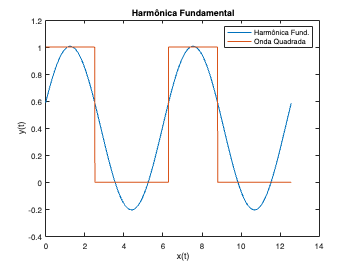

plot(x, partial(:, 1) + A0);
hold on;

plot(x, y);
title('Harmônica Fundamental');
xlabel('x(t)'), ylabel('y(t)');
legend('Harmônica Fund.', 'Onda Quadrada');
hold off;